x = load('1.txt')

x =      0     0     0     0     0   404
     1     0     0     0     0   392
     2     0     0     0     0   372
     3     0     0     0     0   353
     4     0     0     0     0   342
     5     0     0     0     0   348
     6     0     0     0     0   347
     7     0     0     0     0   339
     8     0     0     0     0   334
     9     0     0     0     0   333



S=x(:,6);

waveletFunction = 'db8';
[C,L] = wavedec(  S, 8, waveletFunction);

cD1 = detcoef( C,L,1); %NOISY
cD2 = detcoef(C,L,2); %NOISY
cD3 = detcoef(C,L,3); %NOISY
cD4 = detcoef(C,L,4); %NOISY
cD5 = detcoef(C,L,5); %GAMA
cD6 = detcoef(C,L,6); %BETA
cD7 = detcoef(C,L,7); %ALPHA
cD8 = detcoef(C,L,8); %THETA
cA8 = appcoef(C,L,waveletFunction,8); %DELTA


%%%% Calculation the Details Vectors
D1 = wrcoef('d',C,L,waveletFunction,1); %NOISY
D2 = wrcoef('d',C,L,waveletFunction,2); %NOISY
D3 = wrcoef('d',C,L,waveletFunction,3); %NOISY
D4 = wrcoef('d',C,L,waveletFunction,4); %NOISY
D5 = wrcoef('d',C,L,waveletFunction,5); %GAMMA
D6 = wrcoef('d',C,L,waveletFunction,6); %BETA
D7 = wrcoef('d',C,L,waveletFunction,7); %ALPHA
D8 = wrcoef('d',C,L,waveletFunction,8); %THETA
A8 = wrcoef('a',C,L,waveletFunction,8); %DELTA


sp=10101

sp = 10101

ep=12100

ep = 12100


s=S(sp:ep) %RAW

s =         1018
        1018
        1018
        1018
         929
         939
         994
        1018
        1018
        1018


d5=D5(sp:ep) %GAMMA

d5 =   -32.2721
  -33.1374
  -34.0888
  -35.2036
  -36.5099
  -37.7982
  -38.9176
  -40.3753
  -42.4949
  -45.3404


d6=D6(sp:ep) %BETA

d6 =    88.5954
   89.1840
   89.1943
   88.6423
   87.5448
   85.9175
   83.7942
   81.2162
   78.2397
   74.9469


d7=D7(sp:ep) %ALPHA

d7 =    46.6384
   45.9259
   45.1872
   44.4226
   43.6324
   42.8179
   41.9791
   41.1154
   40.2257
   39.3075


d8=D8(sp:ep) %THETA

d8 =    59.0578
   59.8335
   60.5938
   61.3385
   62.0672
   62.7797
   63.4758
   64.1552
   64.8177
   65.4640


a8=A8(sp:ep) %DELTA

a8 =   829.4028
  830.0074
  830.6040
  831.1925
  831.7730
  832.3454
  832.9098
  833.4664
  834.0154
  834.5571



%{
%%%plotting the alph, beta, gamma, theta etc
plot(s), title("Raw")   %%raw
plot(d5), title("gamma")  %%beta
plot(d6), title("beta")   %%beta
plot(d7), title("alpha")   %%alpha
plot(d8), title("theta")   %%theta
plot(a8), title("delta")   %%theta

%}
sT = transpose(s);
d5T = transpose(d5);
d6T = transpose(d6);
d7T = transpose(d7);
d8T = transpose(d8);
a8T = transpose(a8);

%signals = [sT, d5T, d6T, d7T, d8T, a8T];
signals = [s, d5, d6, d7, d8, a8];

num = [];
temp = [];
for i=1:6
    for j=1:2000
        num = [num, i];
    end
    num = transpose(num);
    temp = [temp, num];
    num = [];
end


seq = 1:1:2000;
seq=transpose(seq);
seq6 = [seq, seq, seq, seq, seq, seq];



plot3(temp,seq6, signals)




%Lomb-Scargle Power Spectrum Estimation 
plomb_s = plomb(s, [], "power", "Pd", []), title("Raw");

plomb_s = 	1.0e+04 *

    0.1751
    0.2781
    0.5909
    0.5115
    0.2591
    0.1202
    0.3821
    0.8883
    1.0926
    0.8966


plomb_d5 =plomb(d5, [], "power", "Pd", []), title("gamma");

plomb_d5 =     2.3995
    1.7265
    0.6919
    0.0025
    1.0457
    1.7315
    0.7373
    0.0049
    1.0299
    1.7429


plomb_d6 =plomb(d6, [], "power", "Pd", []), title("beta");

plomb_d6 = 	1.0e+03 *

    0.0000
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0001
    0.0001
    0.0000
    0.0000


plomb_d7 =plomb(d7, [], "power", "Pd", []), title("alpha");

plomb_d7 = 	1.0e+03 *

    0.0000
    0.0001
    0.0002
    0.0002
    0.0001
    0.0001
    0.0004
    0.0005
    0.0002
    0.0002


plomb_d8 =plomb(d8, [], "power", "Pd", []), title("theta");

plomb_d8 = 	1.0e+03 *

    0.0020
    0.0026
    0.0036
    0.0015
    0.0011
    0.0039
    0.0047
    0.0007
    0.0045
    0.0285


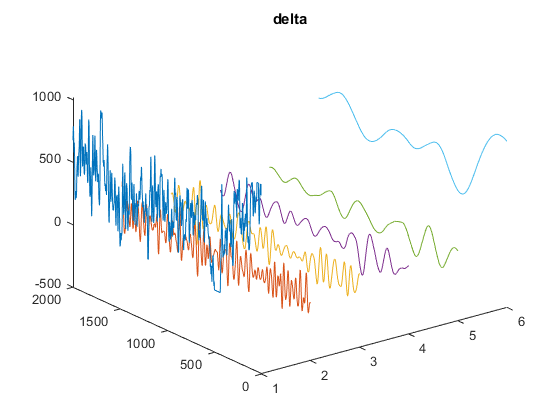

plomb_a8 = 	1.0e+04 *

    0.2003
    0.2901
    0.5751
    0.4930
    0.2650
    0.1453
    0.3859
    0.8834
    1.1374
    1.0189


plomb_a8 =plomb(a8, [], "power", "Pd", []), title("delta");

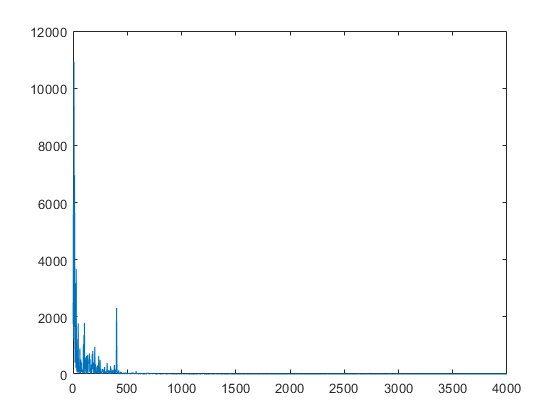


plot(plomb_s)

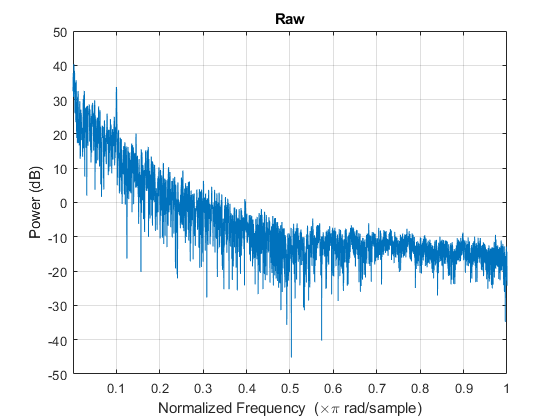

plomb(s, [], "power", "Pd", [] ), title("Raw")

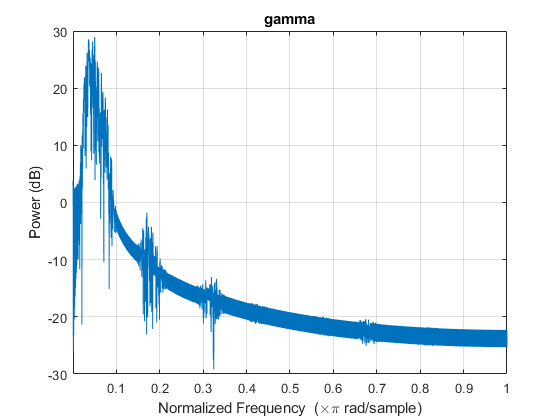

plomb(d5, [], "power", "Pd", []), title("gamma") 

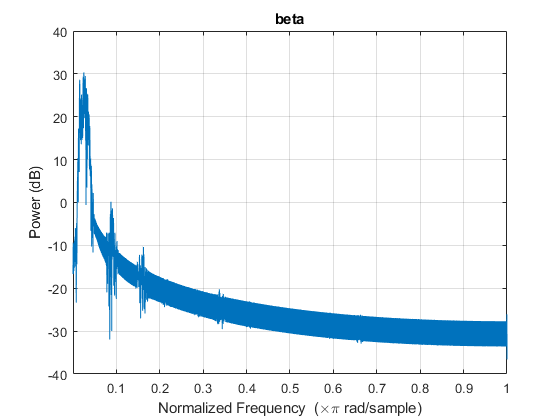

plomb(d6, [], "power", "Pd", []), title("beta")

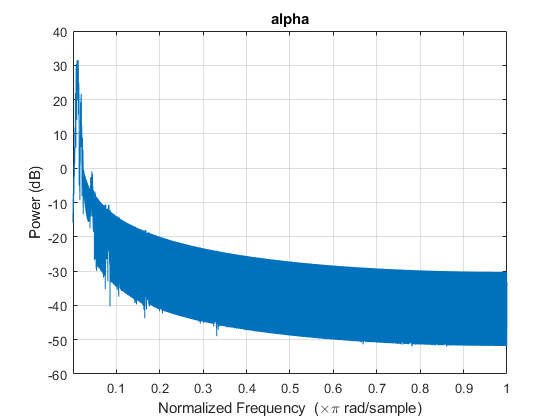

plomb(d7, [], "power", "Pd", []), title("alpha")

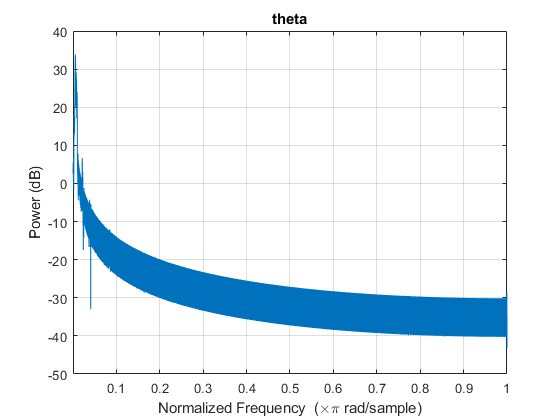

plomb(d8, [], "power", "Pd", []), title("theta") 

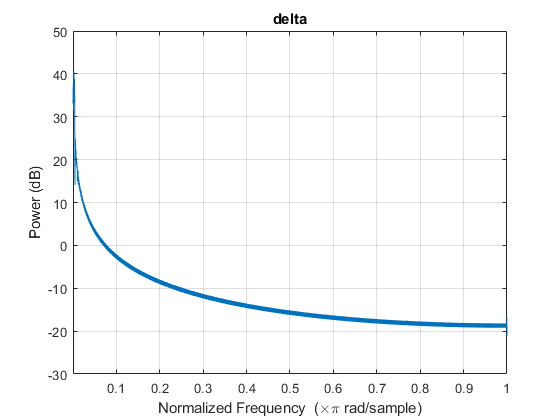

plomb(a8, [], "power", "Pd", []), title("delta") 

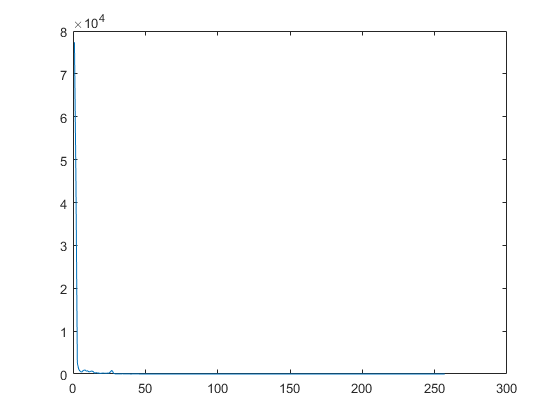



pwelch_s = pwelch(s, [], [], [], 1000);
plot(pwelch_s)

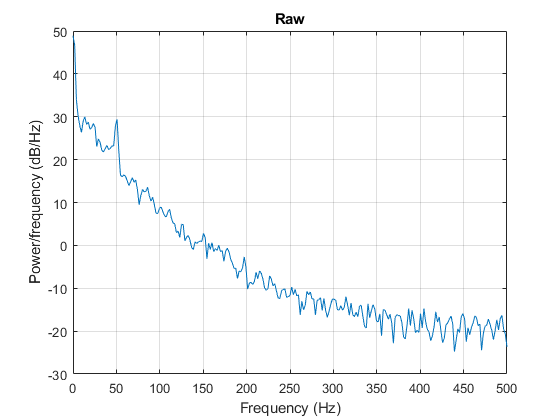

%Welch Power Spectral Density Estimation
figure; pwelch(s, [], [], [], 1000), title("Raw")

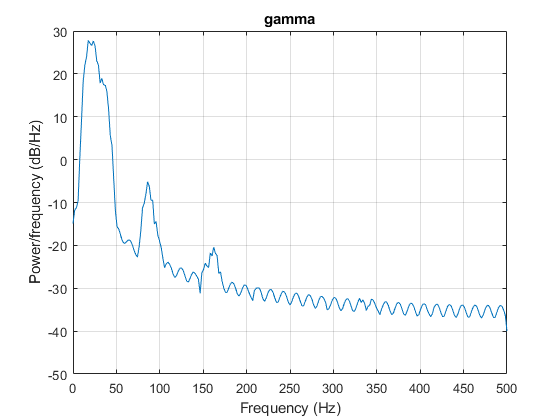

figure; pwelch(d5, [], [], [], 1000), title("gamma") 

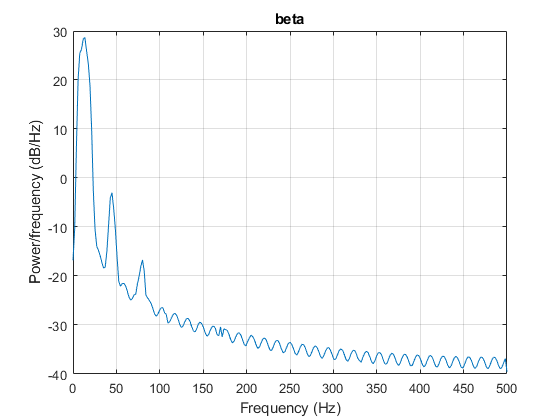

figure; pwelch(d6, [], [], [], 1000), title("beta")

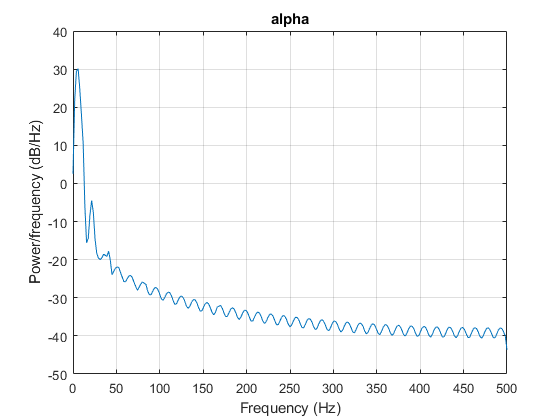

figure; pwelch(d7, [], [], [], 1000), title("alpha")

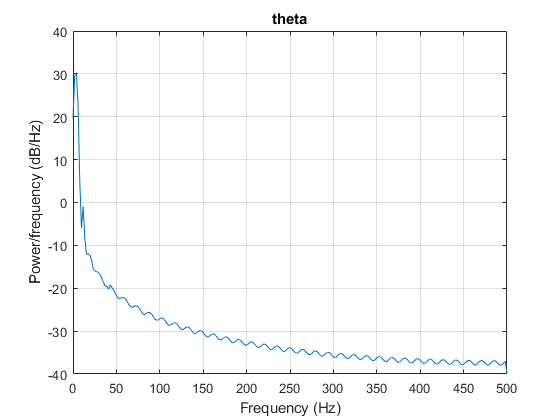

figure; pwelch(d8, [], [], [], 1000), title("theta") 

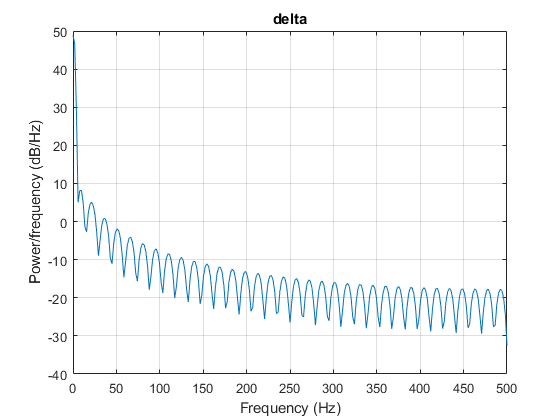

figure; pwelch(a8, [], [], [], 1000), title("delta") 

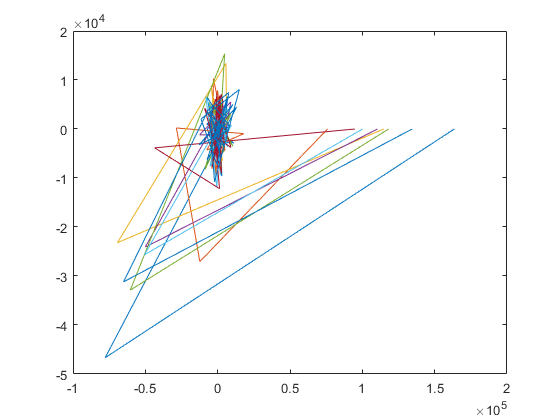



spectrogram_s = spectrogram(s, [],[], [], 1000, 'yaxis');
plot(spectrogram_s)

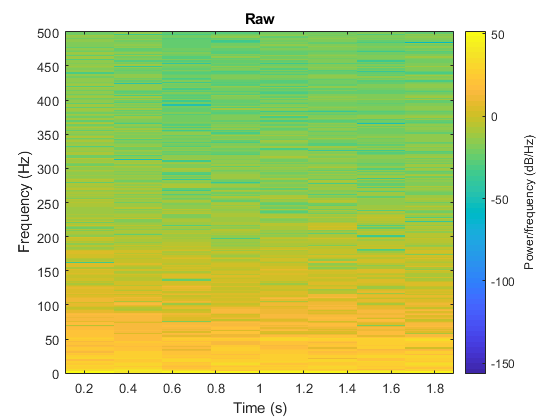

%spectrograms
figure; spectrogram( s, [],[], [], 1000, 'yaxis'), title("Raw")

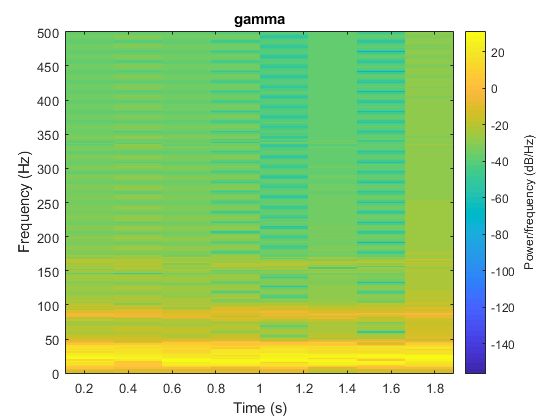

figure; spectrogram(d5, [],[], [], 1000, 'yaxis'), title("gamma") 

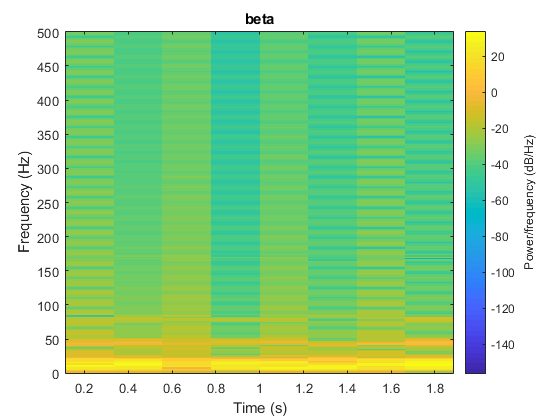

figure; spectrogram(d6, [],[], [], 1000, 'yaxis'), title("beta")

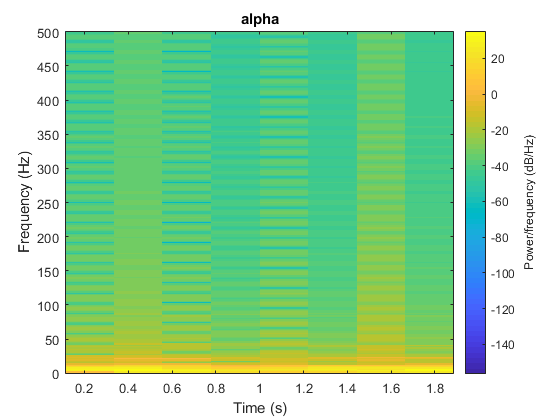

figure; spectrogram(d7, [],[], [], 1000, 'yaxis'), title("alpha")

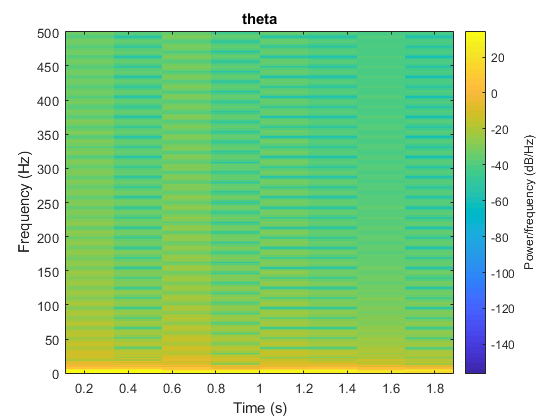

figure; spectrogram(d8, [],[], [], 1000, 'yaxis'), title("theta") 

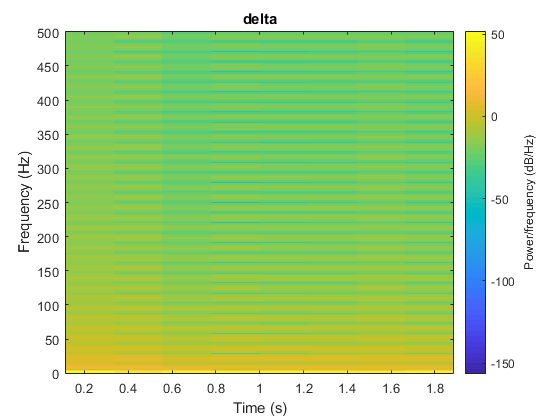

figure; spectrogram(a8, [],[], [], 1000, 'yaxis'), title("delta") 